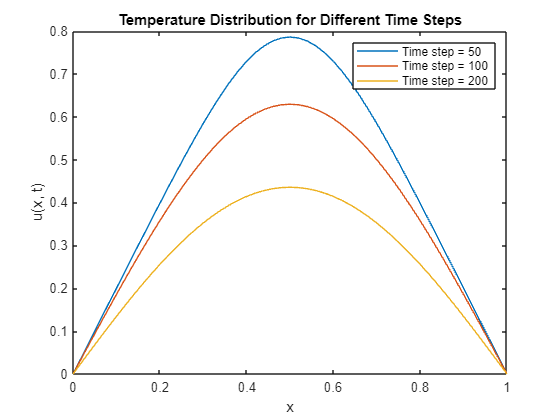

% Parameters
L = 1;          % Length of the rod
n = 50;         % Number of spatial grid points
dx = L / n;     % Spatial step size
F = 0.9;        % Safety factor

% Initialize grid
x = linspace(0, L, n+1);
T0 = zeros(size(x));  % Initial condition
T0(1:n/2+1) = 2 * x(1:n/2+1);  % u(x, 0) for 0 <= x <= 1/2
T0(n/2+2:end) = 2 * (1 - x(n/2+2:end));  % u(x, 0) for 1/2 <= x <= 1

% Time-stepping loop
time_steps = [50, 100, 200];
figure;

for k = 1:length(time_steps)
    nt = time_steps(k);
    dt = F * (dx^2) / 2;
   
    for j = 1:nt
        T1 = zeros(size(T0));
        for i = 2:n
            T1(i) = T0(i) + dt * (T0(i+1) - 2*T0(i) + T0(i-1)) / dx^2;
        end
        T0 = T1;
    end
   
    plot(x, T1, 'DisplayName', ['Time step = ' num2str(nt)]);
    hold on;
end

title('Temperature Distribution for Different Time Steps');
xlabel('x');
ylabel('u(x, t)');
legend;
hold off;